Precision = 1e-3;
Acceptance_Factor = 0.1;
Rejection_Factor = 0.5;
Initial_Conditions =  [1/2, 1];
Time_Period = 2;
Initial_Time = 0;
Number_of_Grid_Points = 25;
Time_Grid = 0:0.02:2;

[Bogacki_Shampine_t, Bogaki_Shampine_Numerical_Solution] = Bogacki_Shampine(@ODE_Q1a, Initial_Time, Time_Period, Initial_Conditions, Number_of_Grid_Points, Precision, Acceptance_Factor, Rejection_Factor);
[SSPK3_t, SSPK3_Numerical_solution] = SSPRK3(@ODE_Q1a, Initial_Time, Time_Period, Initial_Conditions, Number_of_Grid_Points);

Solution_1_Bogaki_Shampine = interp1(Bogacki_Shampine_t, Bogaki_Shampine_Numerical_Solution(1,:), Time_Grid);
Solution_1_SSPK3 = interp1(SSPK3_t, SSPK3_Numerical_solution(1,:), Time_Grid);
Solution_2_Bogaki_Shampine = interp1(Bogacki_Shampine_t, Bogaki_Shampine_Numerical_Solution(2,:), Time_Grid);
Solution_2_SSPK3 = interp1(SSPK3_t, SSPK3_Numerical_solution(2,:), Time_Grid);

Difference_between_y1_solutions = abs(Solution_1_Bogaki_Shampine - Solution_1_SSPK3);
Difference_between_y2_solutions = abs(Solution_2_Bogaki_Shampine - Solution_2_SSPK3);

Maximum_difference = max(Difference_between_y1_solutions,Difference_between_y2_solutions);

disp(['Maximum difference between solutions: ', num2str(max(Maximum_difference))]);

Maximum difference between solutions: 0.0082194


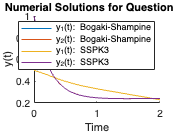


hold on

plot(Bogacki_Shampine_t, Bogaki_Shampine_Numerical_Solution)
plot(SSPK3_t, SSPK3_Numerical_solution)
title('Numerial Solutions for Question 1b')
xlabel('Time')
ylabel('y(t)')
legend('y_1(t): Bogaki-Shampine','y_2(t): Bogaki-Shampine', 'y_1(t): SSPK3','y_2(t): SSPK3')

hold off
saveas(gcf, 'Q1b.png');

function f = ODE_Q1a(t, y)

    f_1 = -2*y(1) + sin(y(2)) + exp(-t)*sin(t);
    f_2 = cos(y(1)) - 4*y(2);

    f = [f_1 f_2]';
end


function [Time, Numerical_Solution] = Bogacki_Shampine(dy_dt, Initial_Time, Time_Period, Initial_Conditions, Number_of_grid_points, Precision, Acceptance_Factor, Rejection_Factor)

    Number_of_stages = 4;
    C_Vector = [0 1/2 3/4 1]';
    B_Matrix = [2/9 1/3 4/9 0 ; 7/24 1/4 1/3 1/8]'; 
    A_Matrix = [0 0 0 0; 1/2 0 0 0; 0 3/4 0 0; 2/9 1/3 4/9 0];

    Time_Step = Time_Period / Number_of_grid_points;
    Time(1) = Initial_Time; 

    Numerical_Solution(:, 1) = Initial_Conditions;
    Number_of_Equations = length(Initial_Conditions);

    K_Matrix = zeros(Number_of_Equations, Number_of_stages);

    Grid_Point = 1;
   
    while Time(Grid_Point) < Initial_Time + Time_Period
        
        for i = 1:Number_of_stages

            t_stage = Time(Grid_Point) + C_Vector(i)*Time_Step;
            u_stage = Numerical_Solution(:, Grid_Point);

            for j = 1:i-1

                u_stage = u_stage + Time_Step * A_Matrix(i, j) * K_Matrix(:, j);
            end

            K_Matrix(:, i) = dy_dt(t_stage, u_stage);
        end

        Updated_Solution = zeros(Number_of_Equations, 1);
        Accuracy_Vector = zeros(Number_of_Equations, 1);

        for i = 1:Number_of_stages

            Updated_Solution = Updated_Solution + B_Matrix(i,1) * K_Matrix(:, i);
            Accuracy_Vector = Accuracy_Vector + B_Matrix(i,2) * K_Matrix(:, i);
        end

        Updated_Solution = Numerical_Solution(:, Grid_Point) + Time_Step * Updated_Solution;
        Accuracy_Vector = Numerical_Solution(:, Grid_Point) + Time_Step * Accuracy_Vector;

        if max(abs((Accuracy_Vector - Updated_Solution) / Time_Step)) < Precision
            
            Numerical_Solution(:, Grid_Point+1) = Updated_Solution;
            Time(Grid_Point+1) = Time(Grid_Point) + Time_Step;
            Grid_Point = Grid_Point + 1;
            Time_Step = (1 + Acceptance_Factor)*Time_Step;
        else
       
            Time_Step = (1 - Rejection_Factor)*Time_Step;
        end
      
        if Time(Grid_Point) + Time_Step > Time_Period
            
             Time_Step = Time_Period - Time(Grid_Point);
        end

    end
end


%----------------------------------------------------------------------------------------------------------

function [t u]=SSPRK3(f,t0,T,y0,N)
%
% SSPRK3 third-order Runge-Kutta method
% -------------------------------------
% The code provides the numerical solution to the vector Cauchy problem 
% dy/dt=f(t,y) on t=t0...t0+T for initial condition y(0)=y0.
%
% Input arguments:
% f - function handle of the right-hand side of the vector Cauchy problem
%     f(t,y), where t is the independent variable, and y is an M x 1
%     (column) vector of the dependent variables
% t0 - initial value of the independent variable
% T - length of the interval
% y0 - an M x 1 (column) vector of the initial values of the dependent variables
% N - number of time steps (the corresponding time step is dt=T/N)
%
% Output variables:
% t - the computational grid (a 1xN vector)
% y - the numerical solution (an MxN matrix) 

% Number of stages
s=3;
% Elements of the Butcher tableau
c=[0 1 1/2];
b=[1/6 1/6 2/3];
A=[0 0 0; 1 0 0; 1/4 1/4 0];

% Time step
dt=T/N;
% Computational grid
t=t0:dt:t0+T;

% Initial condition
u(:,1)=y0;

% Initialization of 'K' vectors 
K=zeros(length(y0),s);

for n=1:N
    for i=1:s
        % Time point for stage 'i'
        ts=t(n)+c(i)*dt;
        % Dependent variables for stage 'i'
        us=u(:,n)+dt*sum(K*diag(A(i,:)),2);
        % Calculating vector 'K' for stage 'i'  
        K(:,i)=f(ts,us);
    end
    % Time advancing step
    u(:,n+1)=u(:,n)+dt*(K*sum(diag(b),2));
end

end        
    